# **LABORATIONSUPPGIFTER I TSDT18/84 SIGNALER & SYSTEM**

# **LABORATION 2**

# **3. Fouriertransformanalys** 

Klicka på [STARTUP] nedan för att initiera Kretslab, innan du börjar med uppgifterna!

 
startup

 
KRETSLAB ÄR INITIERAD!
(Ett antal globala variabler är definierade)
 
För den intresserade (men behövs ej för att lösa uppgifterna):
Om du skriver 'kretslab' i kommandofönstret så öppnas ett
hjälpfönster där tollboxens funktioner är beskrivna.
 


Frekvensspektrumet för den *stationära* *sinussignalen* $s\left(t\right)=\sin \left(2\pi 200t\right)$ består av två dirac-impulser med vikten 1/2 vid frekvenserna $f=-200\;\textrm{Hz}$ och $f=200\;\textrm{Hz}$. Som du ser i Tabell 3:23 i kursens formelsamling, så motsvaras det av två dirac-impulser med vikten $\pi$ vid vinkelfrekvenserna  $\omega =-2\pi \cdot 200$ rad/sek och $\omega =2\pi \cdot 200$ rad/sek.

I uppgifterna nedan ska du bland annat undersöka frekvensegenskaperna hos *tidsbegränsade* sinussignaler $A\cdot s\left(t\right)\cdot p\left(t\right)$, som består av en amplitudskalning (faktorn *A*) av produkten mellan den stationära sinusen och en fyrkantpuls $p\left(t\right)=u\left(t\right)-u\left(t-\tau \right)\ldotp$ Vi börjar i Uppgift 3.1 med att undersöka frekvensegenskaperna hos denna fyrkantspuls, vilket är viktigt för att förstå fortsättningen.

## Uppgift 3.1 – Fyrkantpulsen

Nedan matas fyrkantpulsen $p\left(t\right)=u\left(t\right)-u\left(t-\tau \right)$ med bredd $\tau$ (tau) in och fouriertransformeras. Markera (klicka på) knapparna nedan för att visa fyrkantpulsen $p\left(t\right)$ respektive dess amplitudspektum $\left|P\left(f\right)\right|$ (för $f\ge 0$). Ändra pulsbredden $\tau$ med regeln och studera relationen mellan pulsens utseende och dess amplitudspektrum:

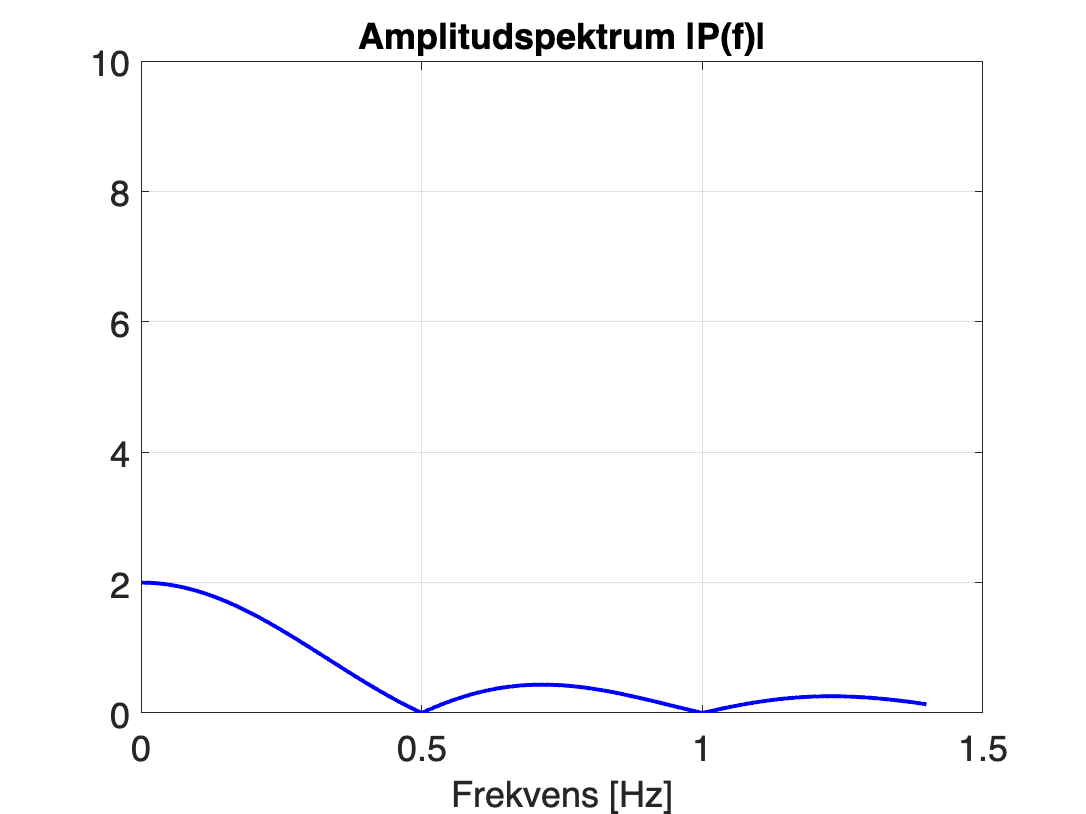

Fyrkantpuls = true;
Spektrum = true;

tau =8;
uppgift31

Pulsens amplitudspektrum är uppenbarligen absolutbeloppet av en sinc-funktion $\left({\textrm{sinc}}_{\mathrm{N}} \left(f\right)=\frac{\sin \left(\pi f\right)}{\pi f}=\textrm{sinc}\left(\pi f\right)\;–\;\textrm{se}\;\textrm{formelsamlingen}\right)$, bestående av en *huvudlob *centrerad kring $f=0$, med avklingande *sidolober*. (I det ritade spektrumet ser vi bara den högra delen av den symmetriska sinc:en, dvs. för $f\ge 0$).

Hur är sinc:ens *toppvärde* och dess *nollgenomgångar* (där $P\left(f\right)=0$) relaterade till utseendet hos fyrkantpulsen $p\left(t\right)?$ 

- Jämför graferna med det analytiska uttrycket i formelsamlingen för fouriertransformen av en fyrkantpuls och bekräfta att sambandet stämmer!  *Detta är centralt för de kommande uppgifterna!*

- Här är höjden hos fyrkantpulsen $p\left(t\right)$ lika med 1. När du svarar ska du ange ett samband som gäller då du **tar med amplitudskalningen *****A*** – dvs. ange hur amplitudspektrumet relateras till en *skalad* fyrkantpuls $A\cdot p\left(t\right)$. 

**☆  ****Svar****:**  

Huvudlobens "höjd" är densamma som tau. Vi ser också att då tau går mot 10 ökar frekvesen mellan sidoloberna i amplitudsspektrumet. 

## Uppgift 3.2 – Sinuspulser

Nedan har de två tidsbegränsade sinussignalerna $s_1 \left(t\right)=\sin \left(2\pi 200t\right)\left(u\left(t\right)-u\left(t-\frac{1}{5}\right)\right)$och $s_2 \left(t\right)=\sin \left(2\pi 200t\right)\left(u\left(t\right)-u\left(t-\frac{1}{40}\right)\right)$matats in. Dessa två sinuspulser kan betraktas som produkten mellan den stationära sinusen och en fyrkantpuls med två olika pulsbredder, $\tau =\frac{1}{5}\;\textrm{sek}$ respektive $\tau =\frac{1}{40}\;\textrm{sek}$, vilket t.ex. kan tolkas som en *amplitudmodulering* av sinusen med två olika fyrkantpulser.

Du ska nu undersöka relationen mellan $s_1 \left(t\right)$ och dess amplitudspektrum $\left|S_1 \left(f\right)\right|$, samt detsamma för $s_2 \left(t\right)$och $\left|S_2 \left(f\right)\right|$. 

**OBS: Ha inte för bråtton med Uppgift 3.2 – en god förståelse för sambanden här är nödvändig för att du ska klara efterföljande uppgifter!**

 
uppgift321

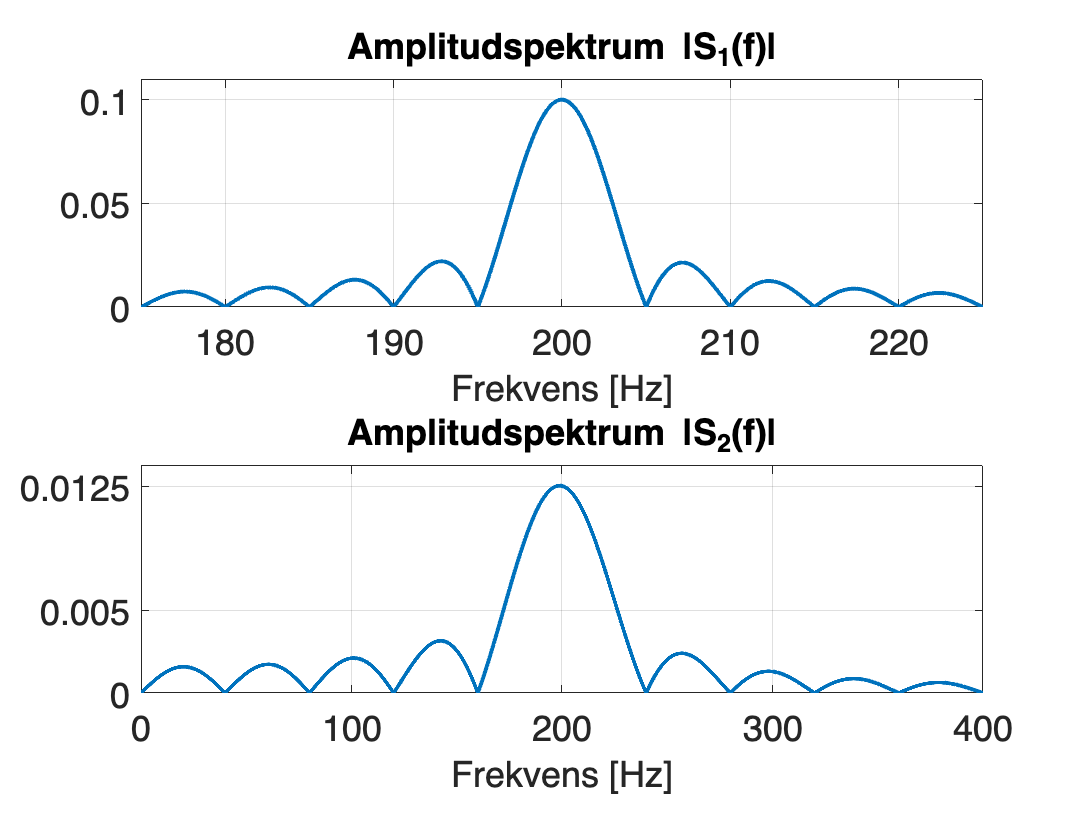

 
uppgift322

### Uppgift 3.2a

Båda amplitudspektrumen $\left|S_1 \left(f\right)\right|$ och $\left|S_2 \left(f\right)\right|$ har en huvudlob med avklingande sidolober (samt, naturligtvis, motsvarande för negativa frekvenser).

Förklara varför så är fallet samt varför respektive huvudlob är centrerad vid en viss frekvens. (*Här är det lämpligt att jämföra med de analytiska uttrycken för *$S_1 \left(f\right)$* och *$S_2 \left(f\right)$ –* du ska svara på en fråga om detta i Uppgift 3.2b nedan.*)

**☆  ****Svar:**  

Huvudloben i amplitudspektrumet representerar den dominerande frekvenskomponenten i signalen. Positionen beror på grundfrekvesnen för signalen, i detta fall 200 Hz. Sidoloberna uppstår på grund av att signaler ofta inte är rent sinusformade. 

### Uppgift 3.2b

De så kallade lobernas bredd och huvudlobens höjd skiljer åt sig för de två amplitudspektrumen. Varför?

Ange, i ditt svar, hur *lobernas bredd* samt *huvudlobens höjd *relateras analytiskt till tidsuttrycket för motsvarande sinusformade signalpuls $s_1 \left(t\right)=\sin \left(2\pi 200t\right)\left(u\left(t\right)-u\left(t-\frac{1}{5}\right)\right)$respektive $s_2 \left(t\right)=\sin \left(2\pi 200t\right)\left(u\left(t\right)-u\left(t-\frac{1}{40}\right)\right)$!

(*Tips: Skriv ned alla relevanta analytiska samband som berörs här och jämför med grafernas utseende. Hur ser t.ex. fouriertransformen till en stationär sinus ser ut m.a.p. frekvens?*)

**☆  ****Svar:**  

Fykrantspulserna har olika pulsbredd. För S1 är den 1/5, och för S2 är den 1/40. Detta bidrar till höjden på huvudloben skiljer sig mellan signalerna. För S1 har vi en kortare periodtid för sidoloberna och för S2 en längre. 

### Uppgift 3.2c 

För både $\left|S_1 \left(f\right)\right|$ och $\left|S_2 \left(f\right)\right|$ gäller att varje sidolob för frekvenser *lägre* än huvudloben har *högre amplitud* än motsvarande sidolob för frekvenser *högre* än huvudloben. Detta syns tydligast i det utritade amplitudspektrumet $\left|S_2 \left(f\right)\right|\;$nedan.

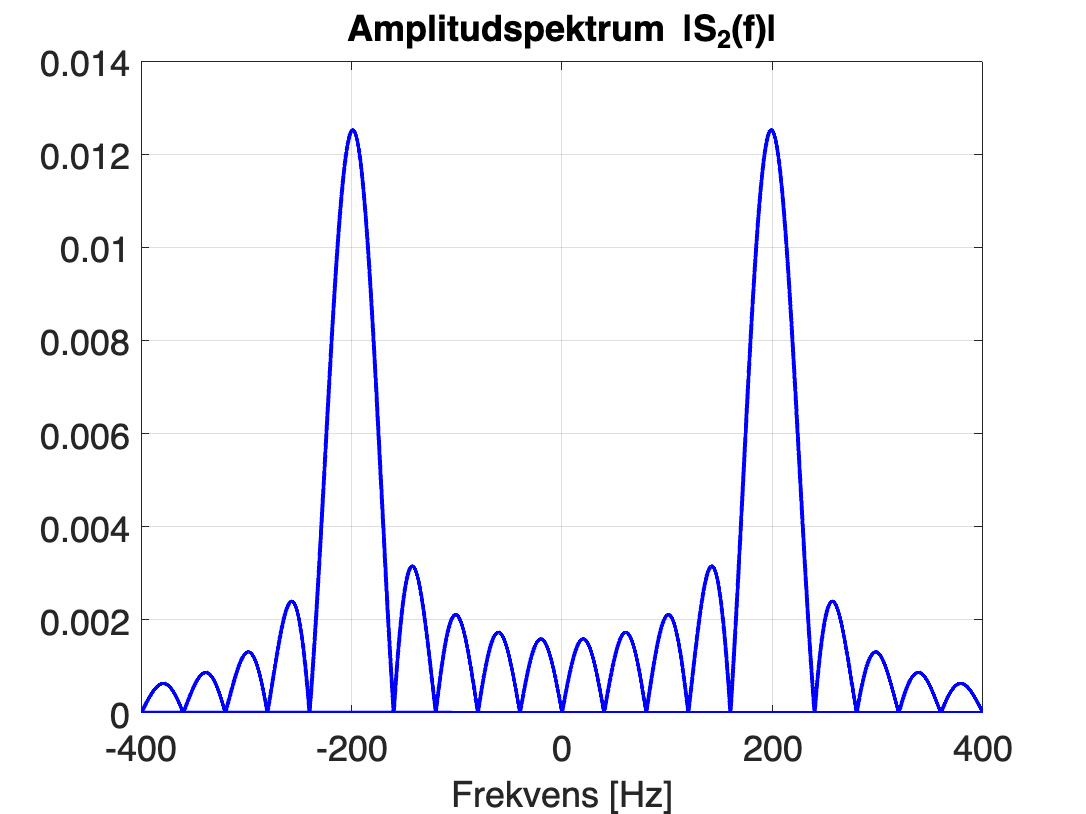

 
uppgift323

Jämför amplitudspektrumet $\left|S_2 \left(f\right)\right|$  för $s_2 \left(t\right)$ med nedanstående amlitudspektrum $\left|S_3 \left(f\right)\right|$  för $s_3 \left(t\right)=\cos \left(2\pi 200t\right)\left(u\left(t\right)-u\left(t-\frac{1}{40}\right)\right),$ där spektrumen är ritade för både negativa och positiva frekvenser. Det enda som skiljer $s_3 \left(t\right)$ från $s_2 \left(t\right)$ ovan är att vi här har en tidsbegränsad *cosinus* i stället för en tidsbegränsad sinus.

(*Bry dig inte om varningstexten om möjlig för stor bandbredd – det är en information som inte spelar roll här.*)

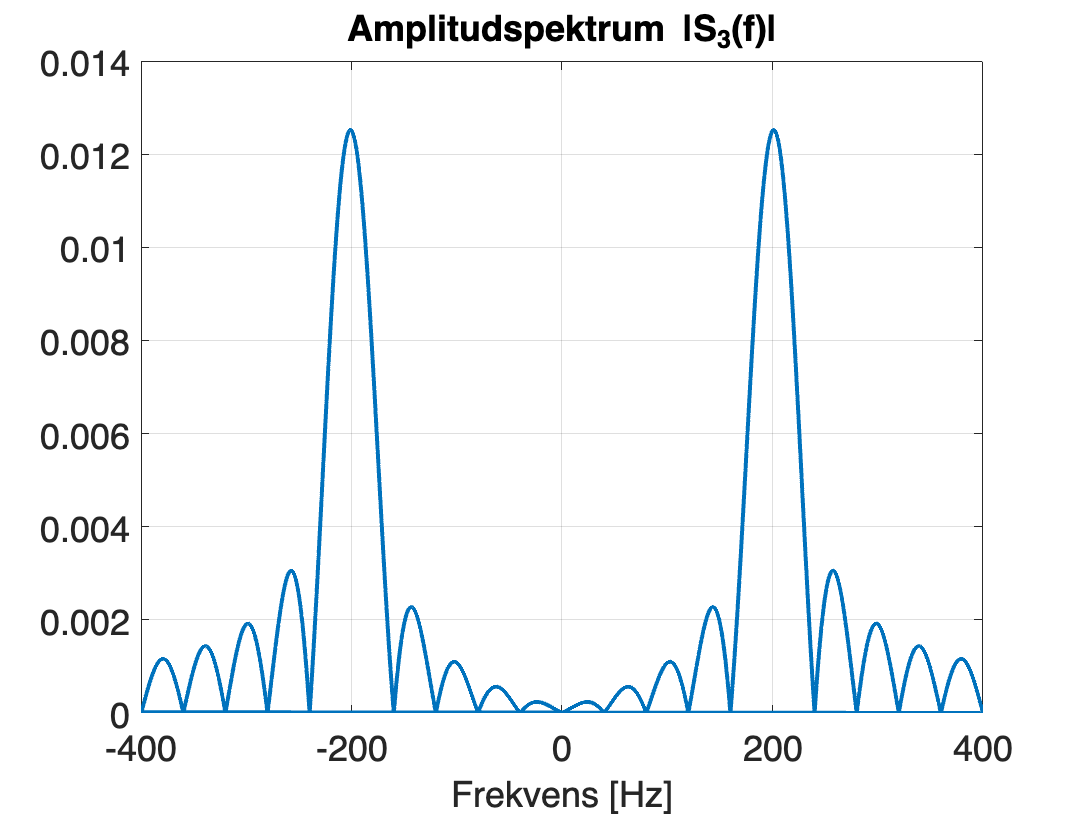

 
uppgift324

Sidoloberna *mellan* huvudloberna i $f=\pm 200$ Hz är högre för $\left|S_2 \left(f\right)\right|$ än för $\left|S_3 \left(f\right)\right|$. 

Varför är det så, är inte sinc-funktionen symmetrisk?

**Komplettera din förklaring med en skiss** – handritad eller lämpliga grafer genererade av dig själv i Matlab eller **Desmos** – och ta hjälp av skissen/grafen när du redovisar för assistenten. 

(*Tips: Här har du hjälp av dina resultat/kunskaper från Uppgift 3.2a och 3.2b. Tänk även på att det i *$s_2 \left(t\right)$*är en sinus medan det i *$s_3 \left(t\right)$*är en cosinus samt att fouriertransformen även har ett innehåll för negativa frekvenser – det är centralt i sammanhanget!*) 

**☆  ****Svar:**  

Vi kan se att för S2 har vi konstruktiv interferens mellan deltonera, och för S3 har vi destruktiv interferens. Detta kan härledas med formelsamkling S.23 formel 22/23. (Ena har + mellan signalerna, andra har -).

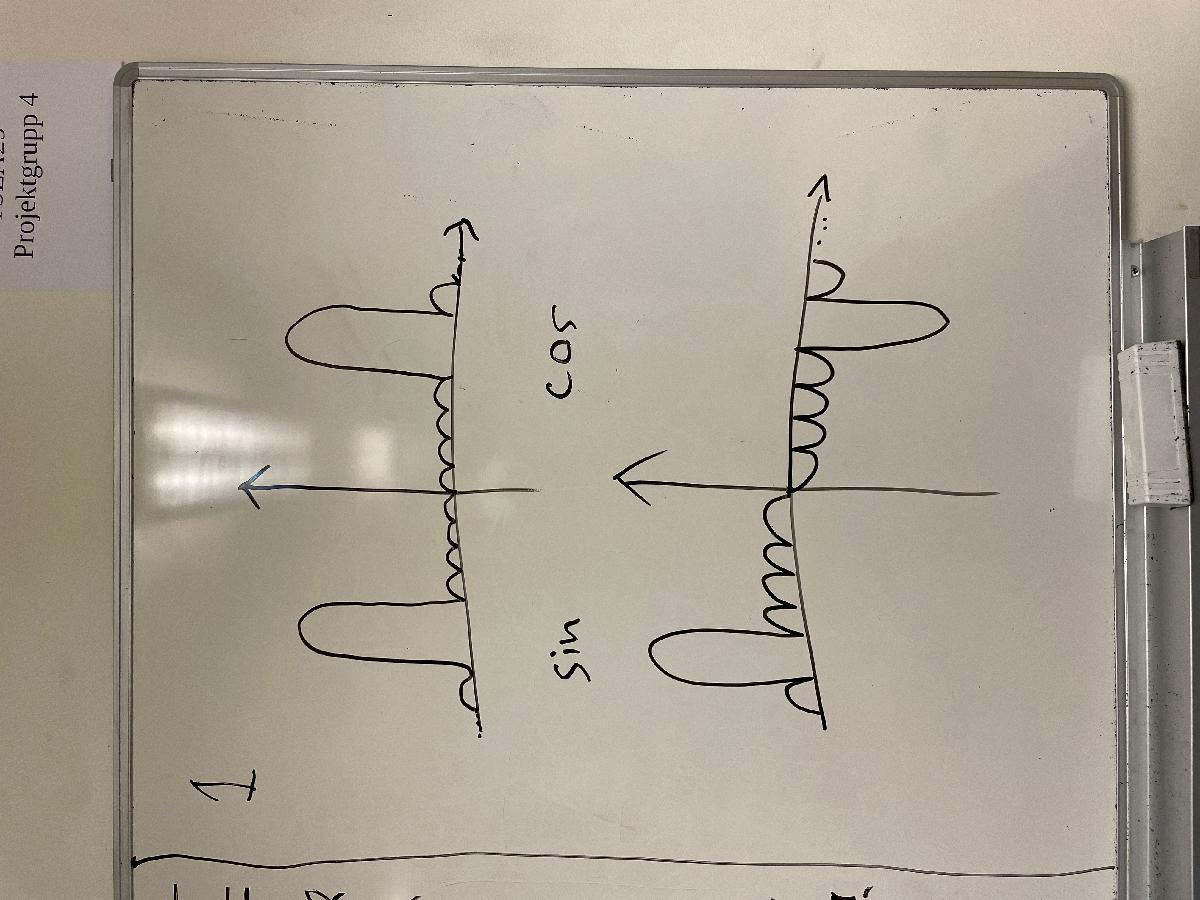

**^^^^^^^ Lägg in din skiss/bildfil här!** Placera markören på raden *innan *detta textstycke, välj fliken "INSERT" längst upp i fönstret och klicka på "Image" för att ladda upp din skiss. 

## Uppgift 3.3 – DTMF-signaler

DTMF (Dual Tone Multiple-Frequency) kallas det tonsignaleringssystem som används då man trycker på en tonvalstelefons knappsats. Tonsignalerna bildas genom att två cosinus-/sinussignaler med olika frekvenser adderas, enligt tabellen nedan.

                  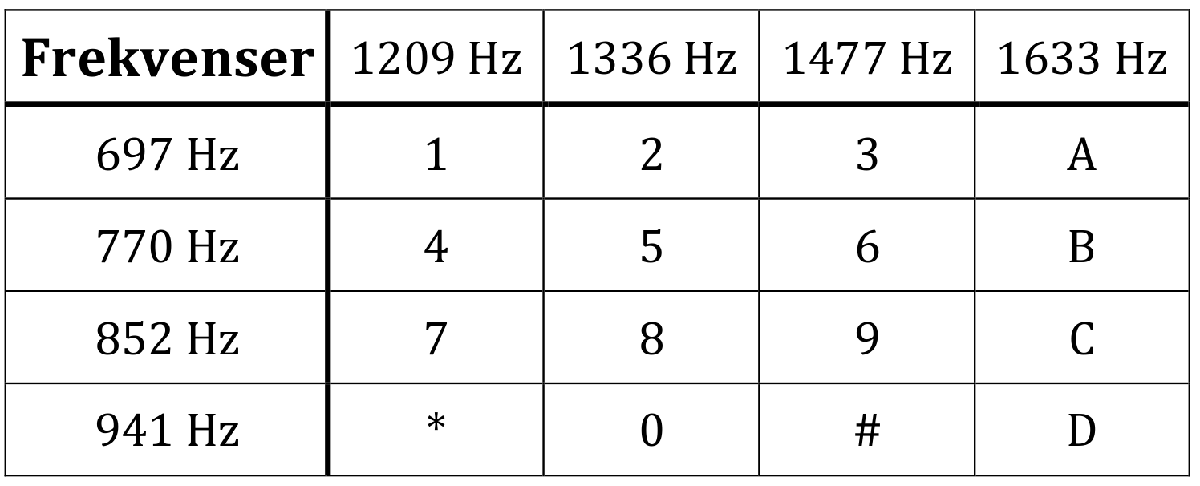

En DTMF-puls som finns i tidsintervallet $t_1 \le t<t_2$ och som består av två sinuspulser med amplitud $A$ och frekvenserna $f_1$ och $f_2$, kan alltså uttryckas på formen $A\cdot \left(\sin \left(2\pi f_1 t\right)+\sin \left(2\pi f_2 t\right)\right)\left(u\left(t-t_1 \right)-u\left(t-t_2 \right)\right)$**.**

Om t.ex. knappen ”9” trycks ned, så sänds alltså ett sinus-signalpar med frekvenserna 852 Hz resp. 1477 Hz. Bokstäverna A−D finns inte på en vanlig knappsats, men används i protokoll för t.ex. nummerpresentatörer. De olika frekvenserna är valda så att ingen av signalerna är överton till någon av de andra signalerna.

Hämta Matlabvariabeln `toner` genom att klicka på knappen nedan (variabeln finns i datafilen **dtmf**). Denna variabel utgör en *samplad version *av en tidskontinuerlig DTMF-signal, som består av ett antal ett antal DTMF-pulser (DTMF-toner). DTMF-signalen är samplad/beräknad i 65536 tidpunkter, med sampelfrekvensen $f_{\mathrm{s}} =6400\;\textrm{Hz},$från ca –5 till +5 sek.

 
load dtmf.mat; disp('DTMF-signalen är hämtad!')

DTMF-signalen är hämtad!


*Anm: I toolboxen Kretslab, som används i laborationen, representeras en tidskontinuerlig signal som en signalvektor av längd 65537, där de 65536 första vektorelementen innehåller sampelvärdena (position 32769 motsvarar *$t=0$*) och element 65537 innehåller sampelperioden *$T_{\mathrm{s}} =\frac{1}{f_{\mathrm{s}} }$.

 
helpwin vartype

I dennas uppgift kommer du att undersöka tidsutseendet och frekvensegenskaperna för hela DTMF-signalen och varje DTMF-puls för sig. Lyssna först på hela DTMF-signalen, genom att klicka på knappen nedan:

 
soundsc(toner(32768:65536), 1/toner(end));  % toner(end) = Ts

**Rita och undersök** den givna DTMF-signalens tidsutseende och dess amplitudspektrum genom att klicka på respektive knapp nedan. 

**Zooma gärna in i graferna** för att se detaljer (*se info om detta under "****Några tips****" i början av live-skriptet för Laboration 1*). 

*Notera att tidssignalens "hackiga" utseende beror på att Matlab har ritat raka streck mellan sampelpunkterna. Om sampelperioden skulle varit lägre, så hade kurvan inte varit lika hackig. Mer om detta längre fram i kursen och i laborationen.* 

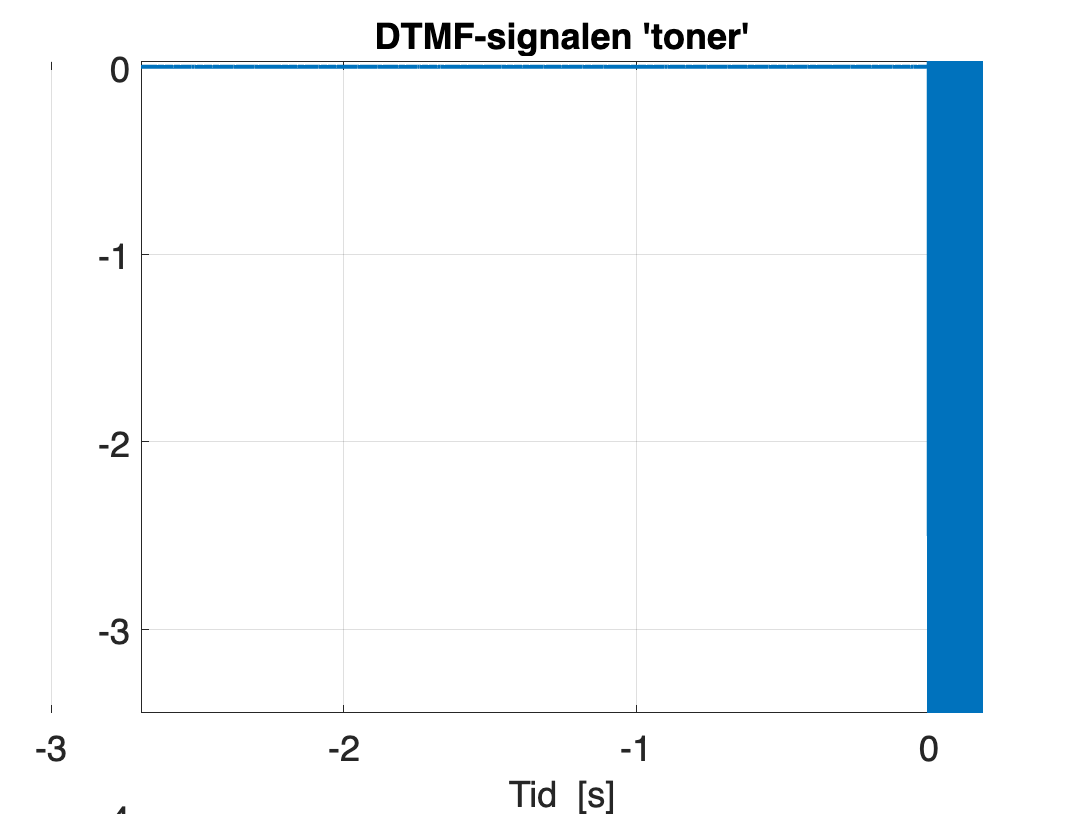

 
uppgift331

xlim([-4.26 5.98])
ylim([-6.7 6.5])

 
uppgift332

### Uppgift 3.3a

Hur många knapptryckningar representerar DTMF-signalen `toner`? Motivera!

☆  **Svar:**  Vi har 16 knapptryckningar.

### Uppgift 3.3b

Kan man direkt ur tidssignalen eller dess amplitudspektrum *visuellt* bestämma den aktuella nummersekvensen? 

Om inte – förklara varför!

☆  **Svar:**  Nej! Vi vet inte ordningen! 

### Uppgift 3.3c

Kan man direkt ur (den här) tidssignalen eller dess amplitudspektrum *visuellt* bestämma om det är några av telefonknapparna som *inte* tryckts ned i nummersekvensen? 

Om svaret är **ja** – ange i så fall vilken/vilka knappar som inte är nedtryckta samt förklara hur du ser detta!

Om svaret är **nej** – förklara varför!

☆  **Svar:**  

Vi kan inte säga exakt vilken tangent som inte trycks, men vi kan se att ingen av tangenterna i kolumnen 1633 Hz kan ses i amplitudsspektrumet, alltså kan omöjligen A, B, C och D ha tryckts ner. 

## Uppgift 3.4 – En enskild DTMF-puls

När du ovan hämtade DTMF-signalen `toner` (i datafilen `dtmf`), så hämtades även Matlabvariabeln `ton`, som utgör *en* enda DTMF-puls. Tryck på knapparna nedan för att rita och undersöka tids- och frekvensegenskaperna för denna enskila DTMF-puls. *Även här är det lämpligt att zooma in i graferna för att undersöka dem närmare. *

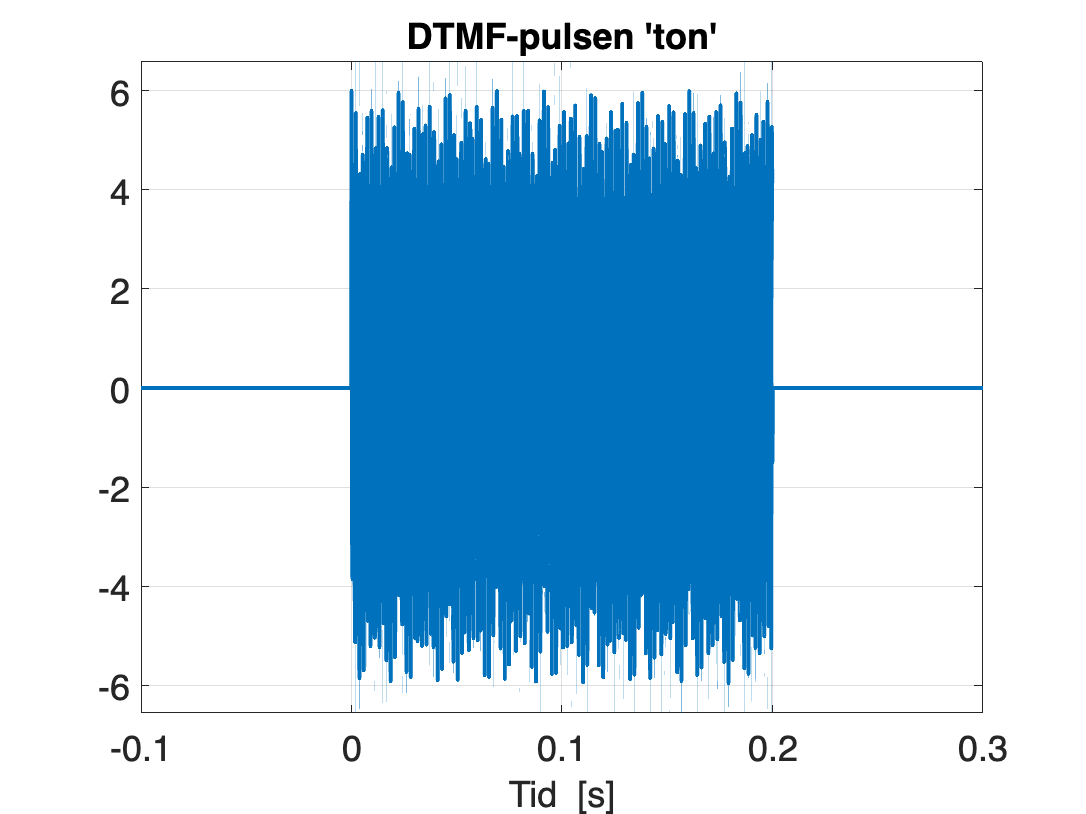

 
uppgift341

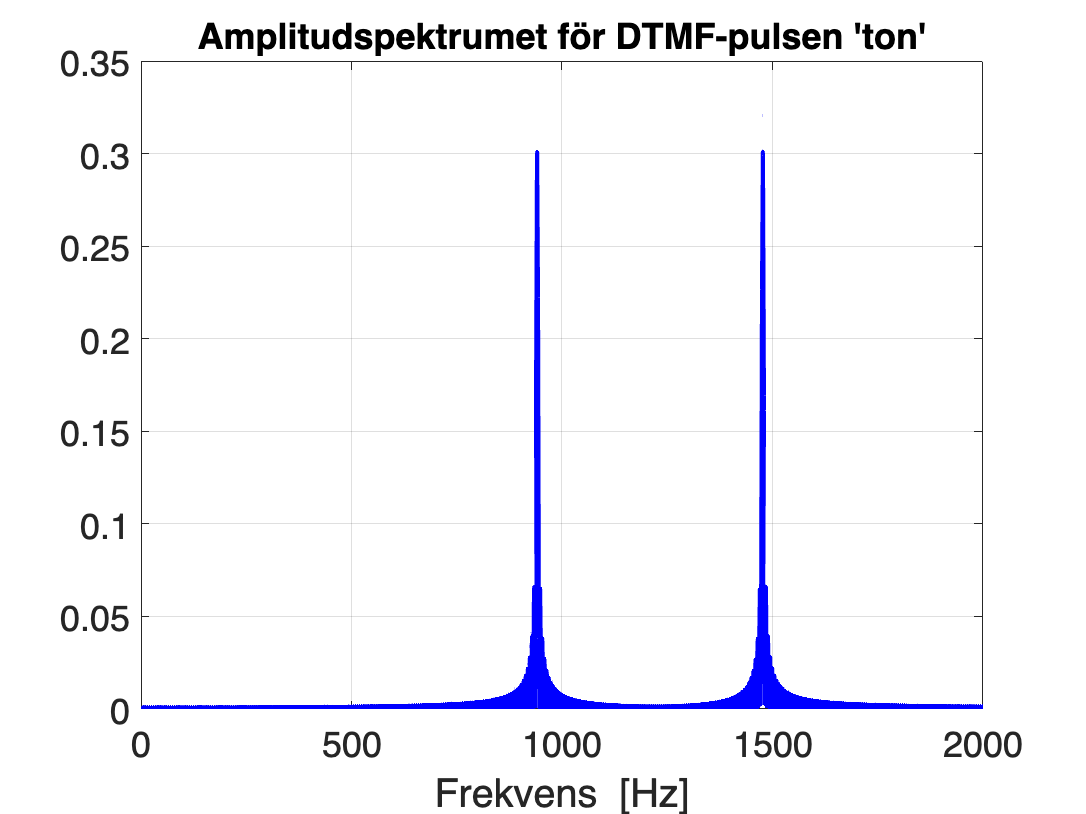

 
uppgift342

### Uppgift 3.4a

Vilken sifferknapp har tryckts ned och gett upphov till denna DTMF-puls? Förklara hur du resonerar!

☆  **Svar:**  #

### Uppgift 3.4b

Vilken amplitud *A* har sinuspulserna i DTMF-pulsen `ton` = $A\cdot \left(\sin \left(2\pi f_1 t\right)+\sin \left(2\pi f_2 t\right)\right)\left(u\left(t-t_1 \right)-u\left(t-t_2 \right)\right)$, som definierades i början av Uppgift 3.3?

- Referera, i din förklaring, till dina slutsatser/resultat i **Uppgift 3.2**, dvs. du ska **förklara hur *****A***** erhålls från DTMF-pulsens *****amplitudspektrum! ***Denna uppgift blir svår om du inte har fått god förståelse för resultaten i Uppgift 3.2.

- Du behöver då bl.a. ta hjälp av det *analytiska uttrycket *för DTMF-pulsens *spektrum/fouriertransform *– använd formelsamlingen och beräkna det som behövs för hand! Det handlar bland annat om hur amplitudskalningen *A *och dirac:ernas vikter påverkar lobernas bredder och höjder för de sinc:ar som ingår i spektrumet. 

- Du får/ska ***inte *****förklara utgående från tidssignalen** (dess analytiska uttryck eller ritad graf). 

- Som stöd för ditt resonemang och din förklaring ovan är det lämpligt att du närmare studerar hur amplitudspektrumet för `ton `ser ut vid dess sinc:ar. Klicka på knappen nedan för att se hur spektrumet ser ut runt *en* av sinc:arna. Du kan även själv zooma in/ut och flytta spektrumet längs frekvensaxeln om du vill, t.ex. för att visa och studera den andra sinc:en:

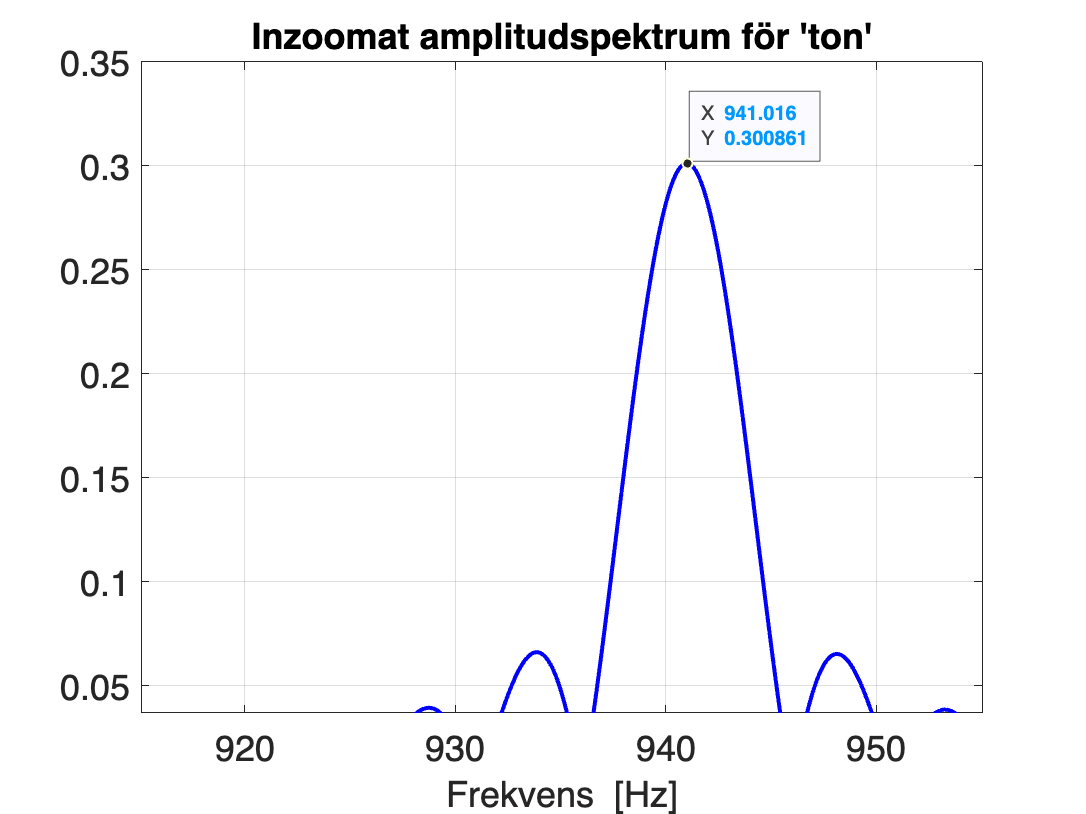

 
uppgift343

☆  **Svar:**  

0,3 / 0,2 = amplitud / tau = amplitudsskalningen

Eftersom vi har dubbelsidigt spektrum multiplicerar vi detta med två och får

(0,3/0,2)*2  = 1,5 * 2 = 3

Dvs A = 3

**Era lösta uppgifter i Laboration 2 ovan redovisas för assistenten under *****REDOVISNINGSPASS 2*****, i enlighet med anvisningarna i introduktionen inför Laboration 1. Laboration 1 ska vara redovisad innan Laboration 2 kan redovisas.**

**Det är lämpligt att ha med formelsamlingen vid redovisningstillfället, för att kunna relatera till samband och transformpar där.**

**Under tiden ni väntar på att det ska bli er grupps tur att redovisa, så fortsätter ni att lösa uppgifter i nästa laboration.**